# Compare HDR versus Burst

experiment with various HDR and other multi-image "burst" algorithms for capturing scenes with a variety of dynamic ranges, as well as object and camera motion.

## Create a pbrt scene we can use

Using pbrt lets us get the highest-fidelity rendering

ieInit();
sceneLuminance = 200

sceneLuminance = 200

numRays = 256

numRays = 256

filmResolution = 256

filmResolution = 256

pbrtLensFile = false

pbrtLensFile = logical
   0


sceneChoice = "CornellBoxReference"

sceneChoice = "CornellBoxReference"

apertureDiameter = 6% in mm

apertureDiameter = 6

if strcmp(sceneChoice, "Cornell Box with Bunny")
    scenePath = 'Cornell_BoxBunnyChart';        
    sceneName = 'cornell box bunny chart';
elseif strcmp(sceneChoice, "CornellBoxReference")
    scenePath = "CornellBoxReference";
    sceneName = "CornellBoxReference";
else
    scenePath = 'ChessSet';
    sceneName = 'chessSet';
end

if pbrtLensFile
    pbrtCPScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, 'sceneLuminance', sceneLuminance, ...
    'lensFile','dgauss.22deg.6.0mm.json',...
    'apertureDiameter', apertureDiameter);
else
    pbrtCPScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, 'sceneLuminance', sceneLuminance);
end

Read 9 materials
Reading C4D geometry information.


## Create our sample camera

Just one module

% some timing code, just to see how fast we run...
setpref('ISET', 'benchmarkstart', cputime); 
setpref('ISET', 'tStart', tic);

% cpBurstCamera is a sub-class of cpCamera that implements simple HDR and Burst
% capture and processing
ourCamera = cpBurstCamera(); 

% We'll use a pre-defined sensor for our Camera Module, and let it use
% default optics for now. We can then assign the module to our camera:
sensor = sensorFromFile('ar0132atSensorRGB'); 
% Cameras can eventually have more than one module (lens + sensor)
% but for now, we just create one using our sensor
ourCamera.cmodules(1) = cpCModule('sensor', sensor); % default

## Let's Look at the Camera we've Created

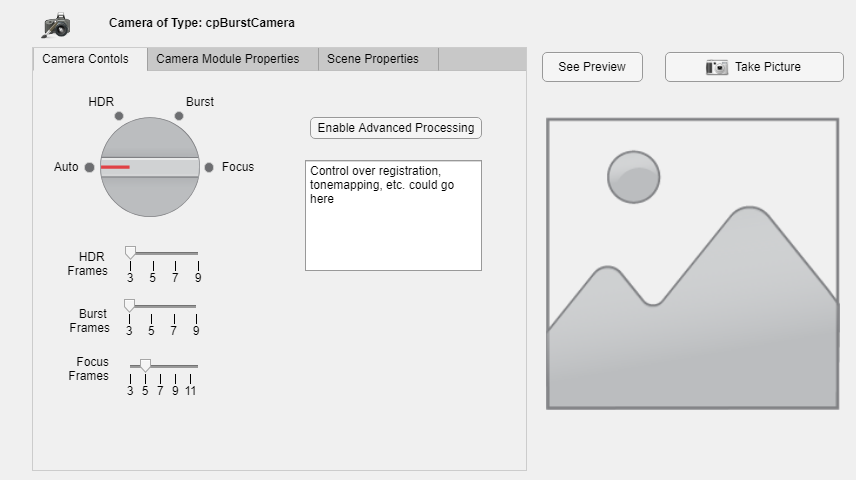

cpCameraWindow(ourCamera, pbrtCPScene);

## Take Pictures using Auto, HDR, and Burst Intents

For the simplest case we ask our camera to take some pictures using pre-defined intents. By deault our camera assumes the 'Auto' intent. We also demonstrate 'Burst', which will capture more frames if the camera type we are using supports it. 'HDR' also fires a burst, but bracketed. Our default camera sums the frames in Burst mode, and chooses the highest non-saturated value at each pixel for HDR mode.

New light added.
Creating output folder C:\iset\iset3d\local\CornellBoxReference\tpd90a2cde_d0a4_44bf_aee9_7f6b130c6afa
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tpd90a2cde_d0a4_44bf_aee9_7f6b130c6afa 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpd90a2cde_d0a4_44bf_aee9_7f6b130c6afa\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpd90a2cde_d0a4_44bf_aee9_7f6b130c6afa\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tpd90a2cde_d0a4_44bf_aee9_7f6b130c6afa -v C:/iset/iset3d/local/CornellBoxReference/tpd90a2cde_d0a4_44bf_aee9_7f6b130c6afa:/tpd90a2cde_d0a4_44bf_aee9_7f6b130c6afa vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: 200.000000"

New light added.
Creating output folder C:\iset\iset3d\local\CornellBoxReference\tp3fa79735_1568_4f3f_b01e_95146568c279
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tp3fa79735_1568_4f3f_b01e_95146568c279 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp3fa79735_1568_4f3f_b01e_95146568c279\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp3fa79735_1568_4f3f_b01e_95146568c279\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tp3fa79735_1568_4f3f_b01e_95146568c279 -v C:/iset/iset3d/local/CornellBoxReference/tp3fa79735_1568_4f3f_b01e_95146568c279:/tp3fa79735_1568_4f3f_b01e_95146568c279 vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: 200.000000"

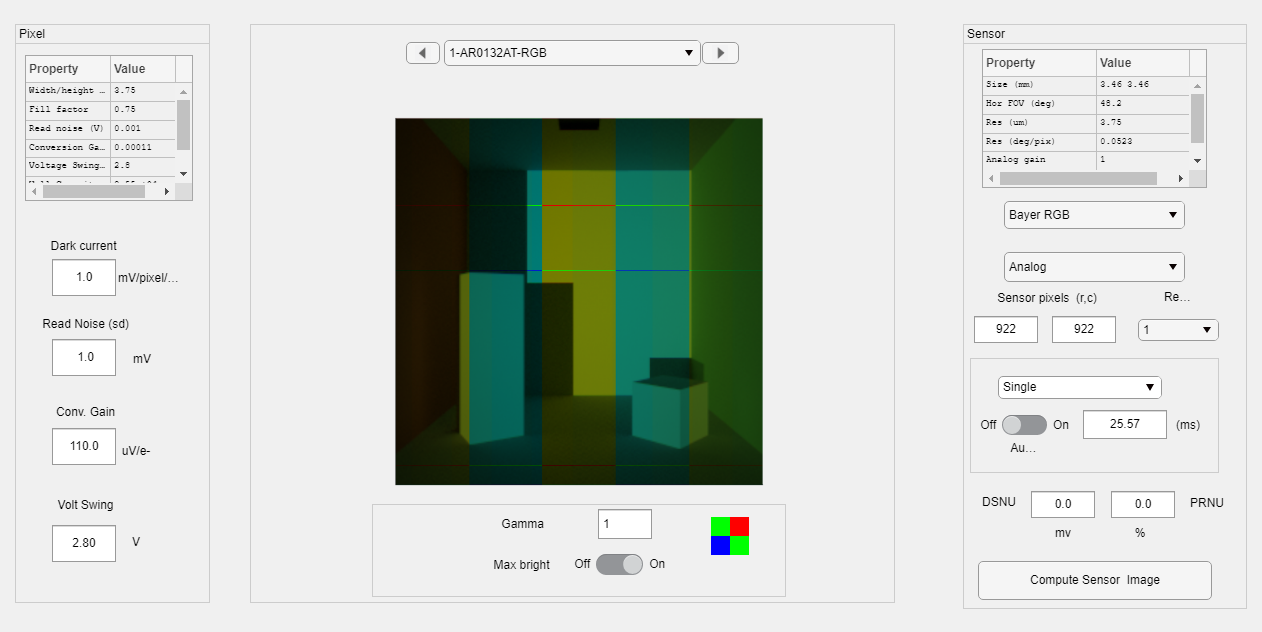

autoImage = ourCamera.TakePicture(pbrtCPScene, 'Auto',...
    'imageName','Auto Mode no motion', 'insensorIP',false); 

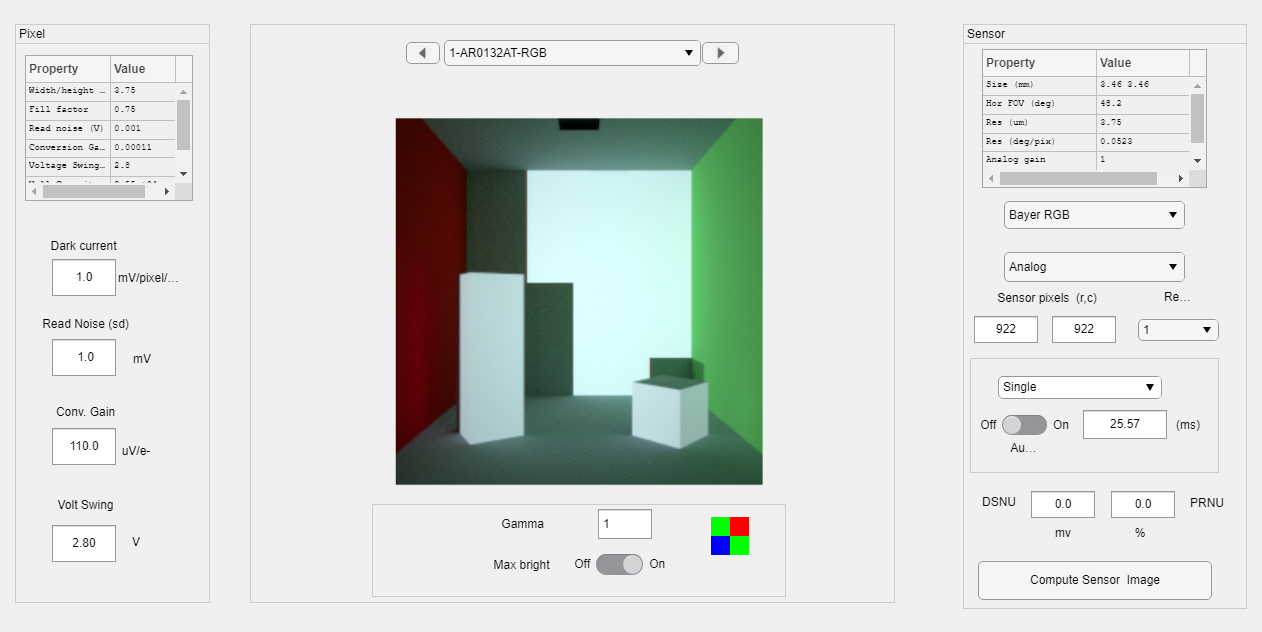

imshow(autoImage);

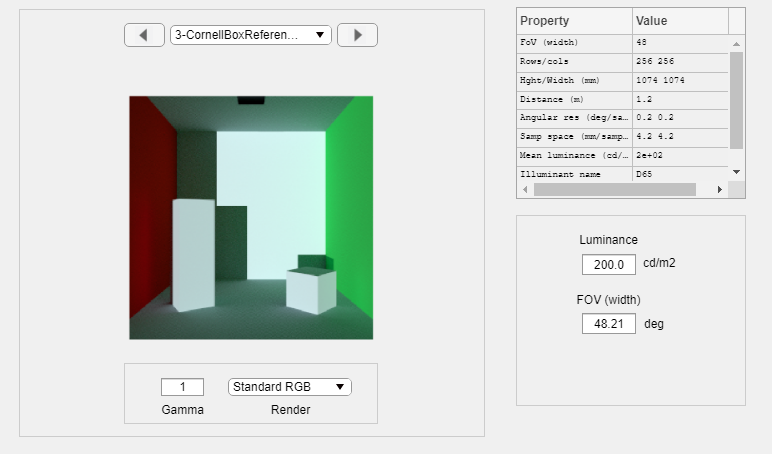

New light added.
Creating output folder C:\iset\iset3d\local\CornellBoxReference\tpeecfe37b_d7ba_4384_ad0c_4fbf1df945d8
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tpeecfe37b_d7ba_4384_ad0c_4fbf1df945d8 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpeecfe37b_d7ba_4384_ad0c_4fbf1df945d8\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpeecfe37b_d7ba_4384_ad0c_4fbf1df945d8\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tpeecfe37b_d7ba_4384_ad0c_4fbf1df945d8 -v C:/iset/iset3d/local/CornellBoxReference/tpeecfe37b_d7ba_4384_ad0c_4fbf1df945d8:/tpeecfe37b_d7ba_4384_ad0c_4fbf1df945d8 vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: 200.000000"

New light added.
Creating output folder C:\iset\iset3d\local\CornellBoxReference\tp2d7172dc_bfdf_4b22_ad41_959f5bfff64c
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tp2d7172dc_bfdf_4b22_ad41_959f5bfff64c 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp2d7172dc_bfdf_4b22_ad41_959f5bfff64c\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp2d7172dc_bfdf_4b22_ad41_959f5bfff64c\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tp2d7172dc_bfdf_4b22_ad41_959f5bfff64c -v C:/iset/iset3d/local/CornellBoxReference/tp2d7172dc_bfdf_4b22_ad41_959f5bfff64c:/tp2d7172dc_bfdf_4b22_ad41_959f5bfff64c vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: 200.000000"

Creating output folder C:\iset\iset3d\local\CornellBoxReference\tpad04015c_fc87_4798_8679_6dbe9e2c896b
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tpad04015c_fc87_4798_8679_6dbe9e2c896b 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpad04015c_fc87_4798_8679_6dbe9e2c896b\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpad04015c_fc87_4798_8679_6dbe9e2c896b\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tpad04015c_fc87_4798_8679_6dbe9e2c896b -v C:/iset/iset3d/local/CornellBoxReference/tpad04015c_fc87_4798_8679_6dbe9e2c896b:/tpad04015c_fc87_4798_8679_6dbe9e2c896b vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReferenc

ans = "Scene luminance is: 200.000000"

Creating output folder C:\iset\iset3d\local\CornellBoxReference\tp6a2e44a1_3c04_4d09_b566_7a05a8196fa5
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tp6a2e44a1_3c04_4d09_b566_7a05a8196fa5 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp6a2e44a1_3c04_4d09_b566_7a05a8196fa5\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp6a2e44a1_3c04_4d09_b566_7a05a8196fa5\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tp6a2e44a1_3c04_4d09_b566_7a05a8196fa5 -v C:/iset/iset3d/local/CornellBoxReference/tp6a2e44a1_3c04_4d09_b566_7a05a8196fa5:/tp6a2e44a1_3c04_4d09_b566_7a05a8196fa5 vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReferenc

ans = "Scene luminance is: 200.000000"


hdrSensorImage = ourCamera.TakePicture(pbrtCPScene, 'HDR',...
    'numHDRFrames', 3,'imageName','HDR in sensor no motion', ...
    'insensorIP', true);

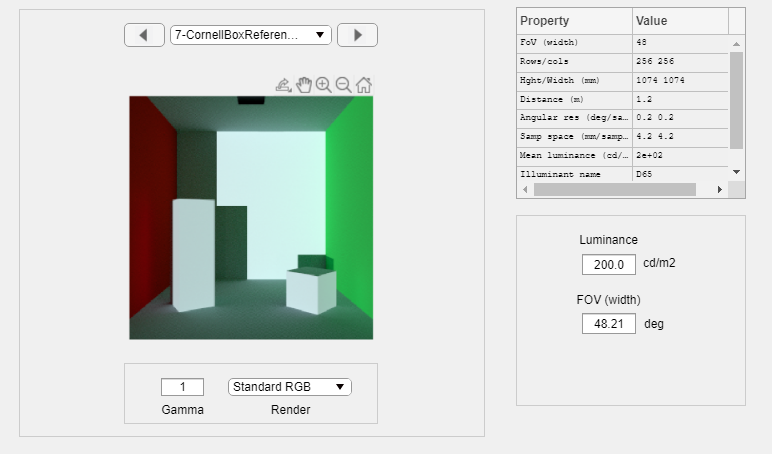

New light added.
Creating output folder C:\iset\iset3d\local\CornellBoxReference\tpafe17f74_9dae_44c2_b7c5_7b449ac30453
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tpafe17f74_9dae_44c2_b7c5_7b449ac30453 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpafe17f74_9dae_44c2_b7c5_7b449ac30453\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpafe17f74_9dae_44c2_b7c5_7b449ac30453\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tpafe17f74_9dae_44c2_b7c5_7b449ac30453 -v C:/iset/iset3d/local/CornellBoxReference/tpafe17f74_9dae_44c2_b7c5_7b449ac30453:/tpafe17f74_9dae_44c2_b7c5_7b449ac30453 vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: 200.000000"

New light added.
Creating output folder C:\iset\iset3d\local\CornellBoxReference\tpdb8e4e8a_ae3a_45b6_bec8_4393b0128b7f
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tpdb8e4e8a_ae3a_45b6_bec8_4393b0128b7f 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpdb8e4e8a_ae3a_45b6_bec8_4393b0128b7f\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpdb8e4e8a_ae3a_45b6_bec8_4393b0128b7f\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tpdb8e4e8a_ae3a_45b6_bec8_4393b0128b7f -v C:/iset/iset3d/local/CornellBoxReference/tpdb8e4e8a_ae3a_45b6_bec8_4393b0128b7f:/tpdb8e4e8a_ae3a_45b6_bec8_4393b0128b7f vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: 200.000000"

Creating output folder C:\iset\iset3d\local\CornellBoxReference\tpb499c852_31ed_4018_a7d2_32ef046ae05f
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tpb499c852_31ed_4018_a7d2_32ef046ae05f 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpb499c852_31ed_4018_a7d2_32ef046ae05f\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpb499c852_31ed_4018_a7d2_32ef046ae05f\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tpb499c852_31ed_4018_a7d2_32ef046ae05f -v C:/iset/iset3d/local/CornellBoxReference/tpb499c852_31ed_4018_a7d2_32ef046ae05f:/tpb499c852_31ed_4018_a7d2_32ef046ae05f vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReferenc

ans = "Scene luminance is: 200.000000"

Creating output folder C:\iset\iset3d\local\CornellBoxReference\tp0af2b38e_2cbd_47c0_b03d_d1ff6820b39a
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tp0af2b38e_2cbd_47c0_b03d_d1ff6820b39a 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp0af2b38e_2cbd_47c0_b03d_d1ff6820b39a\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp0af2b38e_2cbd_47c0_b03d_d1ff6820b39a\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tp0af2b38e_2cbd_47c0_b03d_d1ff6820b39a -v C:/iset/iset3d/local/CornellBoxReference/tp0af2b38e_2cbd_47c0_b03d_d1ff6820b39a:/tp0af2b38e_2cbd_47c0_b03d_d1ff6820b39a vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReferenc

ans = "Scene luminance is: 200.000000"

ipWindow(hdrSensorImage);

burstSensorImage = ourCamera.TakePicture(pbrtCPScene, 'Burst',...
    'numBurstFrames', 3, 'imageName','Burst in Sensor',...
    'insensorIP',true);

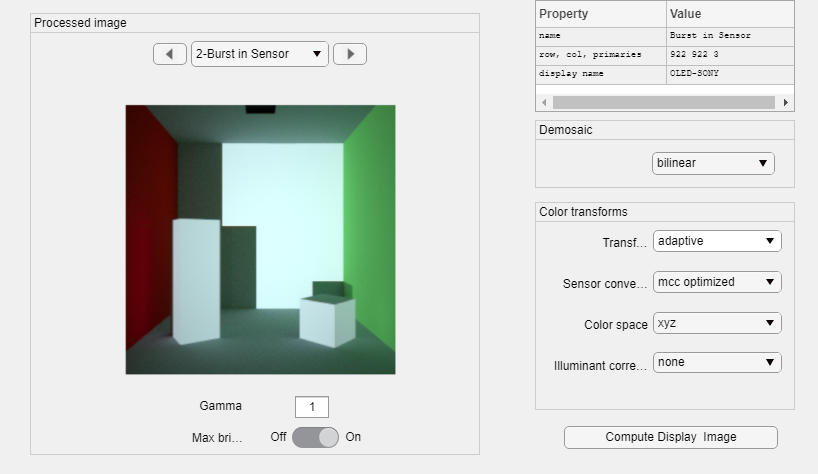

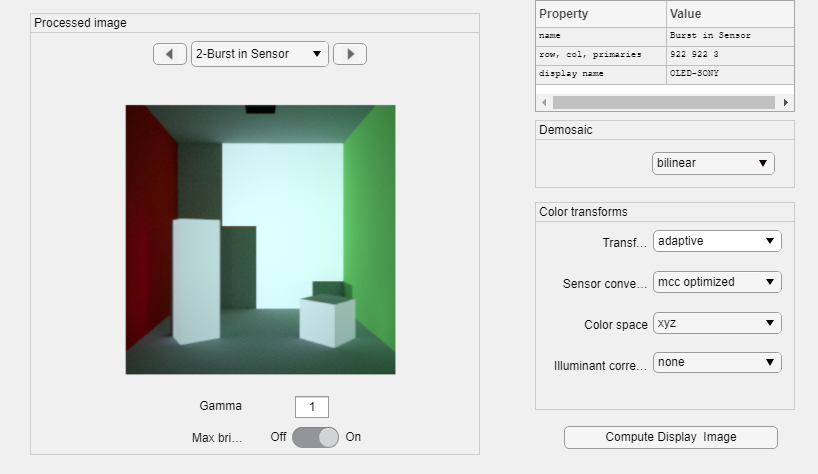

ipWindow(burstSensorImage);

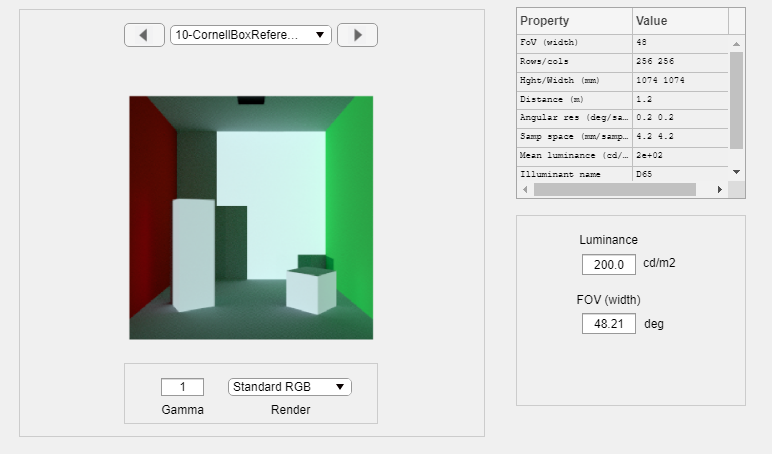

New light added.
Creating output folder C:\iset\iset3d\local\CornellBoxReference\tpc39ef40a_e8ee_40c5_83bb_bab60546b52e
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tpc39ef40a_e8ee_40c5_83bb_bab60546b52e 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpc39ef40a_e8ee_40c5_83bb_bab60546b52e\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpc39ef40a_e8ee_40c5_83bb_bab60546b52e\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tpc39ef40a_e8ee_40c5_83bb_bab60546b52e -v C:/iset/iset3d/local/CornellBoxReference/tpc39ef40a_e8ee_40c5_83bb_bab60546b52e:/tpc39ef40a_e8ee_40c5_83bb_bab60546b52e vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: NaN"

Error using fspecial
Expected input number 3, SIGMA, to be positive.

Error in fspecial>ParseInputs (line 350)
                validateattributes(p3,{'double'},...

Error in fspecial (line 106)
[type, p2, p3] = ParseInputs(varargin{:});

Error in 


%pbrtCPScene.cameraMotion = {{'unused', [.1, 0, 0], [0, 0, 0]}};
hdrMotionImage = ourCamera.TakePicture(pbrtCPScene, 'HDR',...
    'numHDRFrames', 3,'imageName','HDR in ISP with Motion', ...
    'insensorIP', true);

imshow(hdrMotionImage);
imshowpair(hdrImage,hdrMotionImage, 'montage');

burstMotionImage = ourCamera.TakePicture(pbrtCPScene, 'Burst',...
    'numBurstFrames', 3, 'imageName','Burst in ISP with Motion',...
    'insensorIP',false);
imshowpair(hdrMotionImage,burstMotionImage,'montage');
